## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 15 - Example 07 - Plastic Deformation in Truss**

In this example, we will try to study how plastic defromation can affect the behavior of a 2D truss. Most metalic material can be modeled using the bilinear stress-strain relation shown in the bottom line. The material maintains its rigidity before reaching the yielding stress $\sigma_y$. Here, we will look at how the following truss response to the applied loading at mid-span. We will first demonstrate how this can be modeled using the provided plastic bar elements before diving deep into the theory of plasticity.

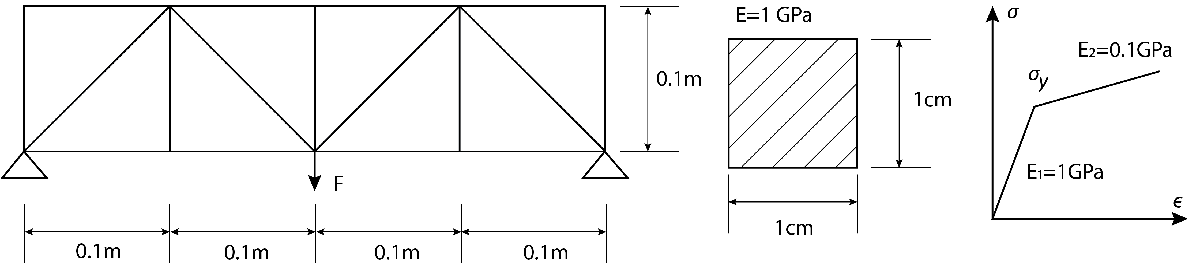

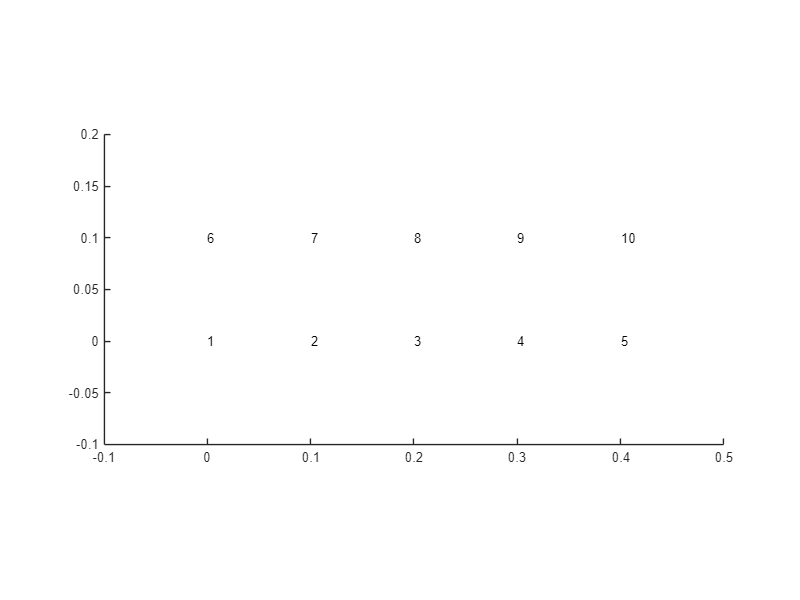

% Initialize Elements
bar=Vec_Elements_Bars_Plastic;
node=Elements_Nodes;

% Create the truss assembly
assembly=Assembly_Truss;
assembly.bar=bar;
assembly.node=node;

% Plotting function
plots=Plot_Truss;
plots.assembly=assembly;
plots.viewAngle1=0;
plots.viewAngle2=0;
plots.displayRange=[-0.1; 0.5; -0.1; 0.1; -0.1; 0.2];


% Define the Geometry of the truss
node.coordinates_mat=[
        0 0 0;
        0.1 0 0;
        0.2 0 0;
        0.3 0 0;
        0.4 0 0;
        0 0 0.1;
        0.1 0 0.1;
        0.2 0 0.1;
        0.3 0 0.1;
        0.4 0 0.1;
    ];

% Plot the nodal coordinates
plots.Plot_Shape_Node_Number();

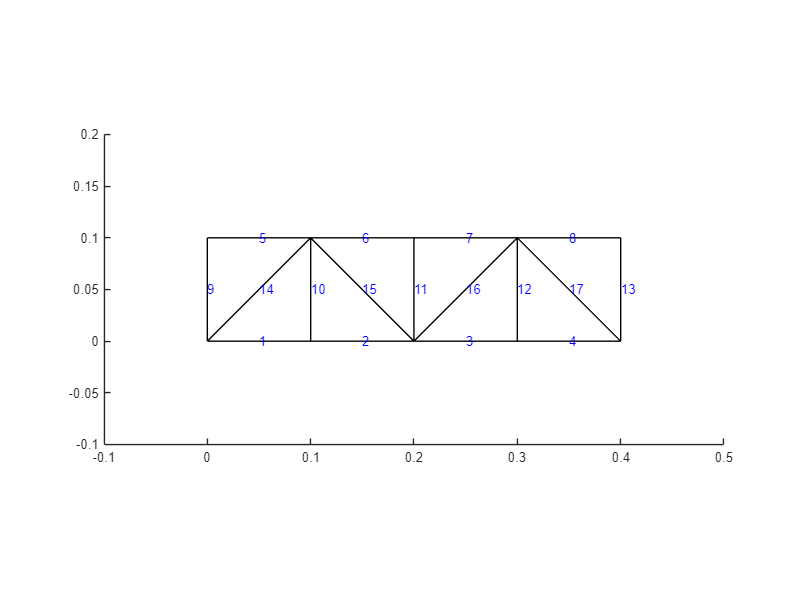

% Define the bar geometry
bar.node_ij_mat=[
    1 2;
    2 3;
    3 4;
    4 5;
    6 7;
    7 8;
    8 9;
    9 10;
    1 6;
    2 7;
    3 8;
    4 9;
    5 10;
    1 7;
    3 7;
    3 9;
    5 9
    ];

barE=1*10^9; % Young's modulus
barH=0.1*10^9; % Harden modulus
barSigmaY=10*10^6; % Yielding stress
barA=0.01*0.01; % Cross section area

bar.E_vec=barE*ones(17,1);
bar.H_vec=barH*ones(17,1);
bar.sigma_y_vec=barSigmaY*ones(17,1);
bar.A_vec=barA*ones(17,1);

assembly.Initialize_Assembly;
plots.Plot_Shape_Bar_Number;

Next, we will use the displacement controlled method tuned to track plastic response for finding the solution. 

%% Setup the loading controller
dc=Solver_DC_Plastic;
dc.assembly=assembly;
dc.supp=[1,1,1,1;
         2,0,1,0;
         3,0,1,0;
         4,0,1,0;
         5,1,1,1;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         ];

force=200;

dc.selectedRefDisp=[3,3];

dc.load=[3,0,0,-force;];

dc.increStep=20;
dc.tol=10^-8;
dc.iterMax=50;

[Uhis,Fhis]=dc.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.701561e-06
    Iteration = 3, R = 1.333193e-10
Icrement = 2
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.674938e-06
    Iteration = 3, R = 1.314386e-10
Icrement = 3
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.648398e-06
    Iteration = 3, R = 1.296111e-10
Icrement = 4
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.621969e-06
    Iteration = 3, R = 1.278414e-10
Icrement = 5
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.595679e-06
    Iteration = 3, R = 1.261338e-10
Icrement = 6
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 4.015449e-04
    Iteration = 3, R = 4.633145e-06
    Iteration = 4, R = 5.152210e-08
    Iteration = 5, R = 5.738157e-10
Icrement = 7
    Iteration = 1, R = 1.719781e-03
    Iteration = 2, R = 1.036016e-05
    Iteration = 3, R = 9.903148e-08
    Iteration = 4, R = 1.095552e-09
Icrement = 8
    Iterat

Now, we can try to find the yielded member in the structure and plot them using the ploted function. To do this, we first find the strain of all the bar elements. Then, we check to see if the strain has exceeded the yielding strain. 

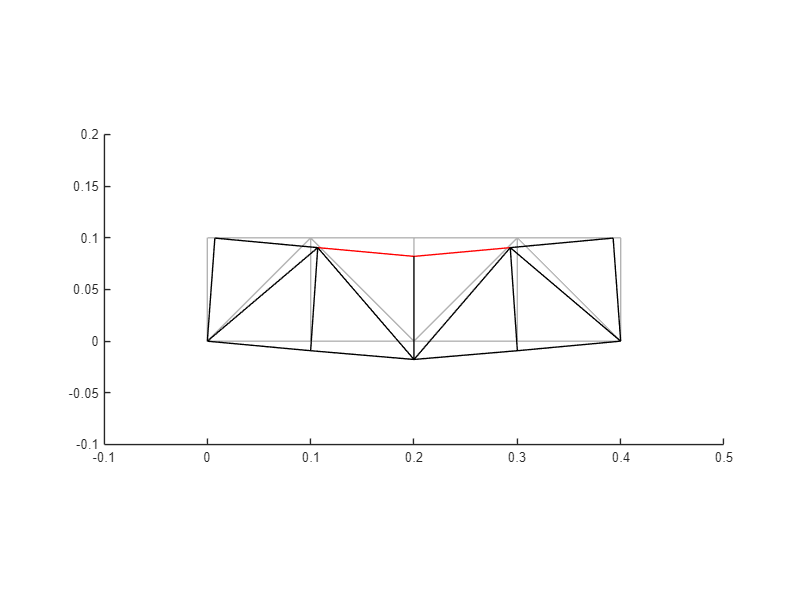

barCurrentStrain=bar.strain_current_vec;
barYieldingStrain=barSigmaY/barE;

% This vector stores if the bar has yielded or not
checkVec=abs(barCurrentStrain)>barYieldingStrain;

plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)),checkVec);

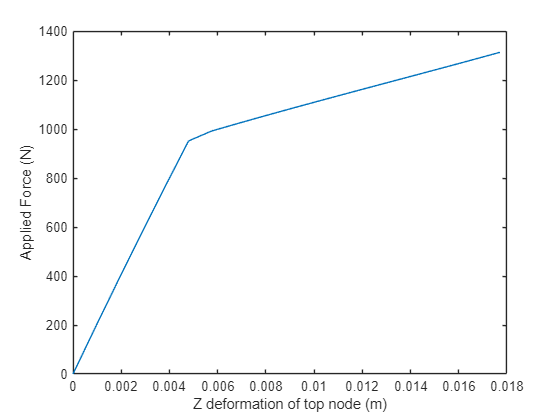

%% Find the reaction force and loading results
FrefHis=zeros(dc.increStep,1);
UrefHis=zeros(dc.increStep,1);

for i=1:dc.increStep
    UrefHis(i)=-Uhis(i,dc.selectedRefDisp(1),dc.selectedRefDisp(2));
    FrefHis(i)=-Fhis(i,(dc.selectedRefDisp(1)-1)*3+dc.selectedRefDisp(2));
end

figure
plot([0;UrefHis],[0;FrefHis])
xlabel('Z deformation of top node (m)') 
ylabel('Applied Force (N)') 

#### **Practice Problems:**

To practice, please consider further working out the following problems. 

#### **Problem 01 **

Now, please use hand calculation to find the yielding force of this truss using the methods we learned in structural analysis. Did that match what we obtain from the simulation? (It should match otherwise Newton will be unhappy ;) )